### Critical Tipping Moment Analysis (from mass test)

g = 9.81; % m/s^2
in2m = 0.0254;

% Measured data points
side_names = {'Perpendicular side', 'Nitrogen tank side'};
arm_in = [28, 26]; % in
mass_g = [965, 1695]; % g

arm_m = arm_in * in2m; % m
mass_kg = mass_g / 1000; % kg
weight_N = mass_kg * g; % N

M_Nm    = weight_N .* arm_m; % N*m
M_lbfin = M_Nm / 0.112985; % lbf*in
M_lbfft = M_Nm / 1.35582; % lbf*ft

%% Summary table

fprintf('\n CRITICAL TIPPING MOMENT SUMMARY \n');


 CRITICAL TIPPING MOMENT SUMMARY 


fprintf('%-22s %8s %10s %12s %12s %12s\n', ...
    'Side', 'Arm(in)', 'Mass(g)', 'M(N*m)', 'M(lbf*in)', 'M(lbf*ft)');

Side                    Arm(in)    Mass(g)       M(N*m)    M(lbf*in)    M(lbf*ft)


for i = 1:length(side_names)
    fprintf('%-22s %8.1f %10.1f %12.3f %12.3f %12.3f\n', ...
        side_names{i}, arm_in(i), mass_g(i), M_Nm(i), M_lbfin(i), M_lbfft(i));
end

Perpendicular side         28.0      965.0        6.733       59.589        4.966
Nitrogen tank side         26.0     1695.0       10.981       97.191        8.099


fprintf('======================================================================\n');

fprintf('Ratio (tank side / perpendicular side): %.2fx\n\n', M_Nm(2)/M_Nm(1));

Ratio (tank side / perpendicular side): 1.63x



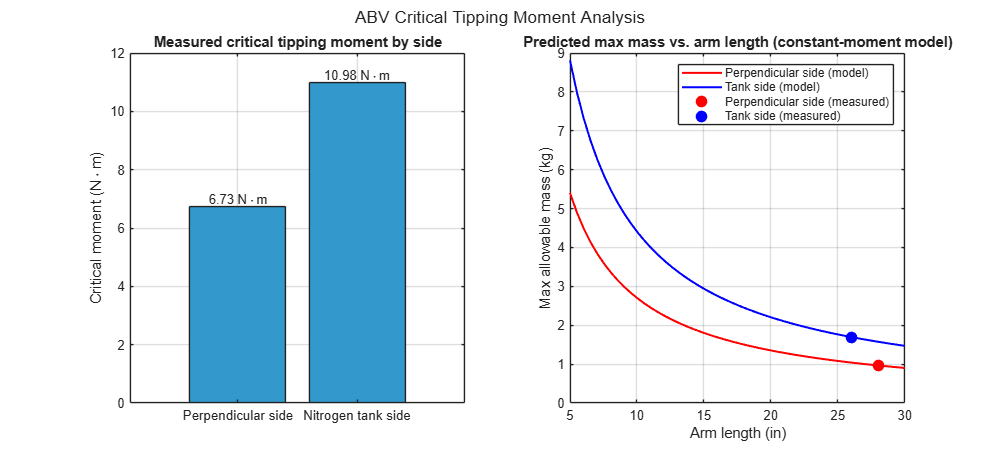


%% Plot 1: direct comparison of measured moments

figure('Name', 'Critical Tipping Moment', 'Position', [100 100 1000 450]);

subplot(1,2,1);
catNames = categorical(side_names, side_names);  % 2nd arg locks category order
bar(catNames, M_Nm, 'FaceColor', [0.2 0.6 0.8]);
ylabel('Critical moment (N\cdotm)');
title('Measured critical tipping moment by side');
grid on;
for i = 1:length(M_Nm)
    text(i, M_Nm(i) + 0.2, sprintf('%.2f N\\cdotm', M_Nm(i)), ...
        'HorizontalAlignment', 'center');
end

%% Plot 2: predicted max allowable mass vs. arm length

arm_sweep_in = linspace(5, 30, 50); % in, sweep of possible arm lengths
arm_sweep_m  = arm_sweep_in * in2m;

m_max_perp_kg = M_Nm(1) ./ (g * arm_sweep_m); % kg, perpendicular side
m_max_tank_kg = M_Nm(2) ./ (g * arm_sweep_m); % kg, tank side

subplot(1,2,2);
plot(arm_sweep_in, m_max_perp_kg, 'r-', 'LineWidth', 1.5); hold on;
plot(arm_sweep_in, m_max_tank_kg, 'b-', 'LineWidth', 1.5);
plot(arm_in(1), mass_kg(1), 'ro', 'MarkerSize', 8, 'MarkerFaceColor', 'r');
plot(arm_in(2), mass_kg(2), 'bo', 'MarkerSize', 8, 'MarkerFaceColor', 'b');
xlabel('Arm length (in)'); ylabel('Max allowable mass (kg)');
legend('Perpendicular side (model)', 'Tank side (model)', ...
       'Perpendicular side (measured)', 'Tank side (measured)', ...
       'Location', 'northeast');
title('Predicted max mass vs. arm length (constant-moment model)');
grid on;

sgtitle('ABV Critical Tipping Moment Analysis');